clear;
close all;
clc;

fprintf('Deriving triple pendulum equations\n');

## Variable Definition

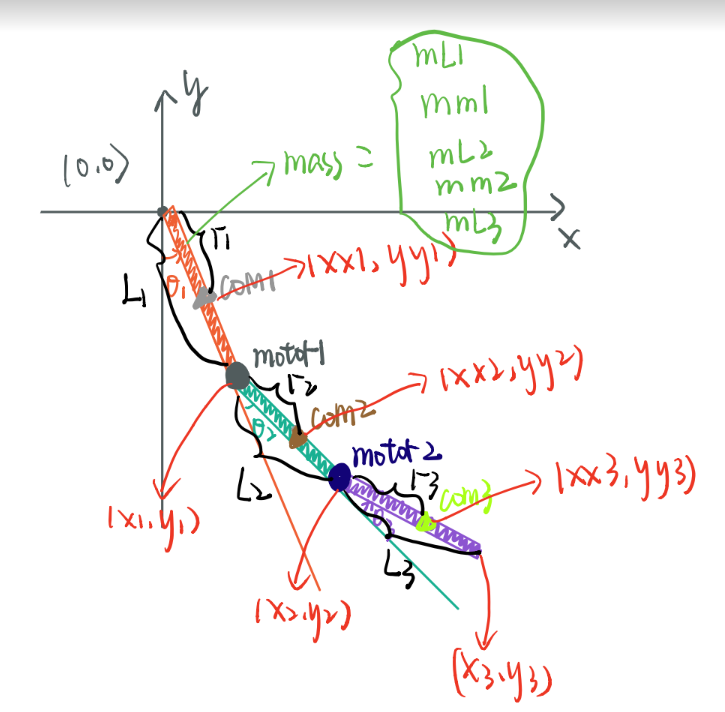

%% Define generalized variables
fprintf('\tInitializing generalized coordinates, velocities, accelerations, and forces...\n');

% Generalized coordinates:
% x: x-location of gripper
% y: y-location of gripper
% theta_1: angle of top link, ccw+ wrt x-axis
% theta_2: angle of mid link, ccw+ wrt top link
% theta_3: angle of bot link, ccw+ wrt mid link
syms x y theta_1 theta_2 theta_3 real
q = [x; y; theta_1; theta_2; theta_3];

% Generalized velocities:
% dx: first derivative of gripper (x)
% dy: first derivative of gripper (y)
% dtheta_1: first derivative of top link angle wrt time
% dtheta_2: first derivative of mid link angle wrt time
% dtheta_3: first derivative of bot link angle wrt time
syms dx dy dtheta_1 dtheta_2 dtheta_3 real
dq = [dx; dy; dtheta_1; dtheta_2; dtheta_3];

% Generalized accelerations:
% ddx: second derivative of gripper (x)
% ddy: second derivative of gripper (y)
% ddtheta_1: second derivative of the top link angle wrt time
% ddtheta_2: second derivative of the mid link angle wrt time
% ddtheta_3: second derivative of the bot link angle wrt time
syms ddx ddy ddtheta_1 ddtheta_2 ddtheta_3 real
ddq = [ddx; ddy; ddtheta_1; ddtheta_2; ddtheta_3];

% Generalized forces:
% tau_s: torque on shoulders (top/mid); positive cw
% tau_h: torque on hips (mid/bot); positive ccw
% syms tau_s tau_m real 
% Q = [0; 0; 0; tau_s; tau_m];

syms u real

fprintf('\t...done.\n');

## Kinetmatics Variable Definition

%% Define kinematics variables
fprintf('\tInitializing kinematics variables...\n');

% x-coordinates of the top, mid, bot links CoM:
syms x_com_top x_com_mid x_com_bot real

% y-coordinates of the top, mid, bot links CoM:
syms y_com_top y_com_mid y_com_bot real

% Dimensions: distance joint to top, mid, bot link CoM:
syms r_com_top r_com_mid r_com_bot real

% Dimensions: length of the top, mid, bot link
syms l_top l_mid l_bot real

% x-coordinates of top, mid, bot tip:
syms x_tip_top x_tip_mid x_tip_bot real

% y-coordinates of top, mid, bot tip:
syms y_tip_top y_tip_mid y_tip_bot real

fprintf('\t...done.\n');

## Inertial and Other Parameters

%% Define inertial (and other) parameters
fprintf('\tInitializing inertial (and other) parameters...\n');

% Mass of top, mid, bot link:
syms m_top m_mid m_bot m_motor1 m_motor2 real

% Rotational inertia of top, mid, bot link:
syms I_top I_mid I_bot real

% Viscous damping at each joint:
b = sym('b',[numel(q),1],'real');
% Note: we'll account for damping at each joint (ground-cart and 
% cart-pendulum) but we can set each damping constant to 0 later if we
% want.

% Other variables
g = sym('g','real'); % gravity
t = sym('t','real'); % time

fprintf('\t...done.\n');

## **Forward Kinematics**

Find the CoM of the top, middle and bottom links in terms of the generalized coordinates.

%% Forward kinematics
fprintf('\tGenerating forward kinematics equations...\n');

% compute the (x,y) location of the top link's CoM:
x_com_top = x + r_com_top*sin(theta_1);
y_com_top = y - r_com_top*cos(theta_1);

% compute the (x,y) location of the top link's tip:
x_tip_top = l_top*sin(theta_1);
y_tip_top = -l_top*cos(theta_1);

%compute the (x,y) location of the mid link's CoM:
x_com_mid = x_tip_top + r_com_mid*sin(theta_1+theta_2);
y_com_mid = y_tip_top - r_com_mid*cos(theta_1+theta_2);

%compute the (x,y) location of the mid link's tip:
x_tip_mid = x_tip_top + l_mid*sin(theta_1+theta_2);
y_tip_mid = y_tip_top - l_mid*cos(theta_1+theta_2);

%compute the (x,y) location of the bot link's CoM:
x_com_bot = x_tip_mid + r_com_bot*sin(theta_1+theta_2+theta_3);
y_com_bot = y_tip_mid - r_com_bot*cos(theta_1+theta_2+theta_3);

%compute the (x,y) location of the bot link's tip:
x_tip_bot = x_tip_mid + l_bot*sin(theta_1+theta_2+theta_3);
y_tip_bot = y_tip_mid - l_bot*cos(theta_1+theta_2+theta_3);

% create a 2x6 array to hold all forward kinematics (FK) outputs:
FK = [x_com_top, x_tip_top, x_com_mid, x_tip_mid, x_com_bot, x_tip_bot;
      y_com_top, y_tip_top, y_com_mid, y_tip_mid, y_com_bot, y_tip_bot];
  
% generate a MATLAB function to compute all the FK outputs:
matlabFunction(FK,'File','autogen_fwd_kin');
% Note: this autogenerated function will make plotting/animation easier
% later. Could also help with some control tasks.
fprintf('\t...done.\n');

## Constraint Equations

Write out constraint equations that keep the gripper at the first bar with (x,y) location at (0, 2)

fprintf('\tInitializing constraint variables...\n');

%constraint variables
syms c_x c_y real

%first bar
c_x = x;
c_y = y;

% create arrayx to hold constraints:
C = [c_x; c_y];

fprintf('\t...done.\n');
fprintf('\tGenerating constraint equations...\n');

% generate MATLAB functions to compute all the constraints:
matlabFunction(C,'File','autogen_constraints');
fprintf('\t...done.\n');

## Derivatives

We take the derivatives of the forward kinematics and the constraint equations

fprintf('\tGenerating time derivatives of the kinematics equations...\n');
derivative = @(in)( jacobian(in,[q;dq])*[dq;ddq] );

% CoM x-velocities:
syms dx_com_top dx_com_mid dx_com_bot real
% CoM y-velocities:
syms dy_com_top dy_com_mid dy_com_bot real

dx_com_top = derivative(x_com_top); % x velocity top link
dy_com_top = derivative(y_com_top); % y velocity top link
dx_com_mid = derivative(x_com_mid); % x velocity mid link
dy_com_mid = derivative(y_com_mid); % y velocity mid link
dx_com_bot = derivative(x_com_bot); % x velocity bot link
dy_com_bot = derivative(y_com_bot); % y velocity bot link

% Constraint equations first and second derivatives
A = derivative(C);
H_x = hessian(c_x,q);
H_y = hessian(c_y,q);

% generate MATLAB functions for the Jacobians and Hessians:
matlabFunction(dx_com_top, dy_com_top,...
               dx_com_mid, dy_com_mid,...
               dx_com_bot, dy_com_bot,'File','autogen_jacobians');
matlabFunction(A, H_x, H_y,'File','autogen_constraint_derivatives');

fprintf('\t...done.\n');

## Kinetic Energy

Sum up:

- Top link translational

- Top link rotational

- Middle link translational

- Middle link rotational

- Bottom link translational

- Bottom link rotational

fprintf('\tGenerating kinetic energy equation...\n');

syms ke_top ke_mid ke_bot KE real

% kinetic energy of each link:
ke_top = (1/2)*m_top*(dx_com_top^2 + dy_com_top^2) + (1/2)*I_top*(dtheta_1^2); 
ke_mid = (1/2)*(m_mid + m_motor1 + m_motor2)*(dx_com_mid^2 + dy_com_mid^2) + (1/2)*I_mid*(dtheta_2^2);
ke_bot = (1/2)*m_bot*(dx_com_bot^2 + dy_com_bot^2) + (1/2)*I_bot*(dtheta_3^2);

% total kinetic energy:
KE = ke_top + ke_mid + ke_bot;

fprintf('\t...done.\n');

## Potential Energy

Sum up:

- Top link potential

- Middle link potential

- Bottom link potential

fprintf('\tGenerating potential energy equation...\n');

syms pe_top pe_mid pe_bot PE real

% potential energy of each link:
pe_top = m_top * g * y_com_top;
pe_mid = (m_mid + m_motor1 + m_motor2) * g * y_com_mid;
pe_bot = m_bot * g * y_com_bot;

%total potential energy:
PE = pe_top + pe_mid + pe_bot;

fprintf('\t...done.\n');

## **For Plotting KE, PE, and Total Energy**

% Total Energy
syms Total_E real
Total_E =  PE + KE;
matlabFunction(KE,'File','autogen_KE');
matlabFunction(PE,'File','autogen_PE');
matlabFunction(Total_E,'File','autogen_Total_E');

## Euler-Lagrange Equations

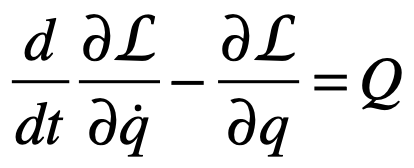

fprintf('\tGenerating Euler-Lagrange equations of motion...\n')

syms L real
L = KE - PE;

% Variable initializations:
ELeq_term1  = sym('ELeq_term1',[numel(q),1],'real'); % d(del L/del dq)/dt
ELeq_term2  = sym('ELeq_term2',[numel(q),1],'real'); % del L/del qa
ELeq_damping= sym('ELeq_damping',[numel(q),1],'real'); % joint damping
ELeq_LHS    = sym('ELeq_LHS',[numel(q),1],'real');

for i = 1:numel(q)
    ELeq_term1(i) = simplify(derivative(diff(L,dq(i))));
    ELeq_term2(i) = simplify(diff(L,q(i)));
    ELeq_damping(i) = -b(i)*dq(i);
    ELeq_LHS(i) = ELeq_term1(i) - ELeq_term2(i) - ELeq_damping(i);
    ELeq_LHS(i) = simplify(ELeq_LHS(i));
end
fprintf('\t...done.\n')

## Putting the Euler-Lagrange EQs in Manipulator Form

fprintf('\tPutting Euler-Lagrange equations into manipulator form...\n');
fprintf('\t\tBuilding M, C, and G...\n');

M = sym('M',[numel(q),numel(q)],'real');
C = sym('C',[numel(q),numel(q)],'real');
G = sym('G',[numel(q),1],'real');

for i = 1:numel(q)
    fprintf('\t\ti = %d\n',i);
    fprintf('\t\t\tM(%d,:)...\n',i)
    for j = 1:numel(q)
        fprintf('\t\t\t\tj = %d\n',j);
        M(i,j) = diff(ELeq_LHS(i),ddq(j));
        M(i,j) = simplify(M(i,j));
    end
    
    fprintf('\t\t\tG(%d)...\n',i)
    G(i) = diff(ELeq_LHS(i),g)*g; % G is linear in g
    
    fprintf('\t\t\tC(%d)...\n',i);
    % C*dq is everything else:
    for j = 1:numel(q)
        fprintf('\t\t\t\tj = %d\n',j);
        C(i,j) = diff((ELeq_LHS(i) - (M(i,:)*ddq + G(i))),dq(j));
    end
    C(i) = simplify(C(i)); % takes some time to execute
end
fprintf('\t\t...done building M, C, and G.\n');

% compute and store inv(M):
fprintf('\t\tComputing inv(M)...\n')
Minv = sym('Minv',[numel(q),numel(q)],'real');
Minv = simplify(inv(M));
fprintf('\t\t...done.\n')

fprintf('\t\tGenerating MATLAB functions...\n');
matlabFunction(M,'File','autogen_mass_matrix');
matlabFunction(C,'File','autogen_coriolis_matrix');
matlabFunction(G,'File','autogen_grav_vector');
fprintf('\t\t...done.\n');

fprintf('\t...done putting Euler-Lagrange equations into manipulator form.\n');

## Generating State-Space Model from Manipulator Equation

fprintf('\tConverting manipulator equation to state-space form...\n');

f_ss = sym('f_ss',[2*numel(q),1],'real'); % drift vector field
g_ss = sym('g_ss',[2*numel(q),2],'real'); % control vector field

temp_drift = simplify(-Minv*(C*dq + G)); % TODO, also use simplify(...)
temp_ctrl = simplify(Minv*[0,0; 1,0; 0,1]); % actuators at shoulders and hips

% Build state-space representation:
for i = 1:numel(q)
    f_ss(i) = dq(i);
    g_ss(i,:) = 0;
    f_ss(i+numel(q)) = temp_drift(i);
    g_ss(i+numel(q),:) = temp_ctrl(i,:);
end

matlabFunction(f_ss,'File','autogen_drift_vector_field');
matlabFunction(g_ss,'File','autogen_control_vector_field');

fprintf('\t...done converting manipulator equation to state-space form.\n');

## Linearizing State-Space Model about Upright Equilibrium

fprintf('\tLinearizing the dynamics about the upright equilibrium...\n')

% upright equilibrium:
theta_1 = 0; %theta_1 defined ccw+ w.r.t. x-axis
theta_2 = 0; %theta_2 defined ccw+ w.r.t. top link
theta_3 = 0; %theta_3 defined ccw+ w.r.t. mid link
dtheta_1 = 0;
dtheta_2 = 0;
dtheta_3 = 0;

% Note: we have been talking about x for a while above but haven't needed
% to define it as a symbolic variable until now:
x = [q; dq]; % just makes the code below easier to read)

% define the equilibrium state:
x_eq = [theta_1; dtheta_1; theta_2; dtheta_2; theta_3; dtheta_3];

% Step 1 of Taylor series approximation is to compute Jacobians:
f_ss_jac = jacobian(f_ss,x); % Jacobian of f_ss
g_ss_jac = g_ss; % Jacobian of g_ss*u

% Evaluate Jacobians at the upright equilibrium:
A = simplify(subs(f_ss_jac,x,x_eq));
B = simplify(subs(g_ss_jac,x,x_eq));

fprintf('\t...done linearizing the dynamics about the upright equilibrium.\n')

matlabFunction(A,'File','autogen_upright_state_matrix');
matlabFunction(B,'File','autogen_upright_input_matrix');
fprintf('...done deriving cart-pendulum equations.\n');